# HElmar Grobauslegung

Konzeptfahrzeug HElmar

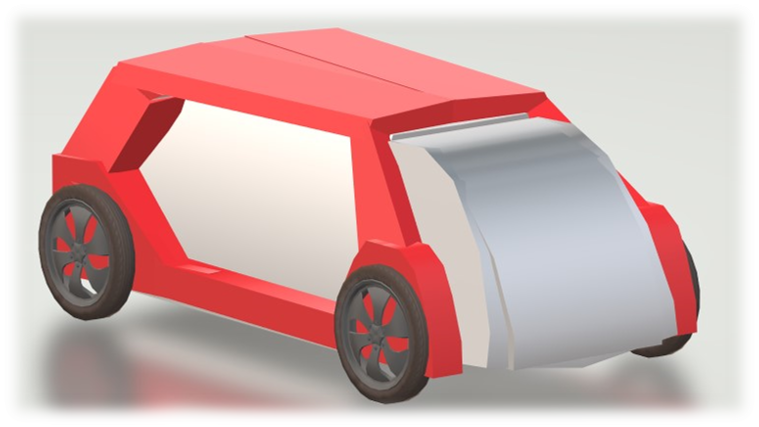

## Daten Gesamtfahrzeug

m=780; % Rover mit 2 GEM Motoren a 30kg: 450 kg; Batterie 190 kg, Fahrer 75 kg; Beifahrer 65 kg; 
g=9.81;
f_R=0.01;
r_A=0.3;
rho=1.2;
c_w=0.31;
A=2;

## Radnabenantrieb (in Anlehnung an elaphe S400 Motor)

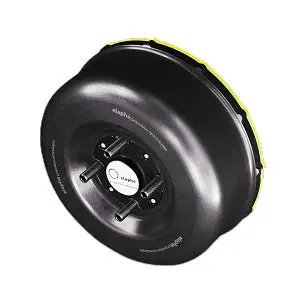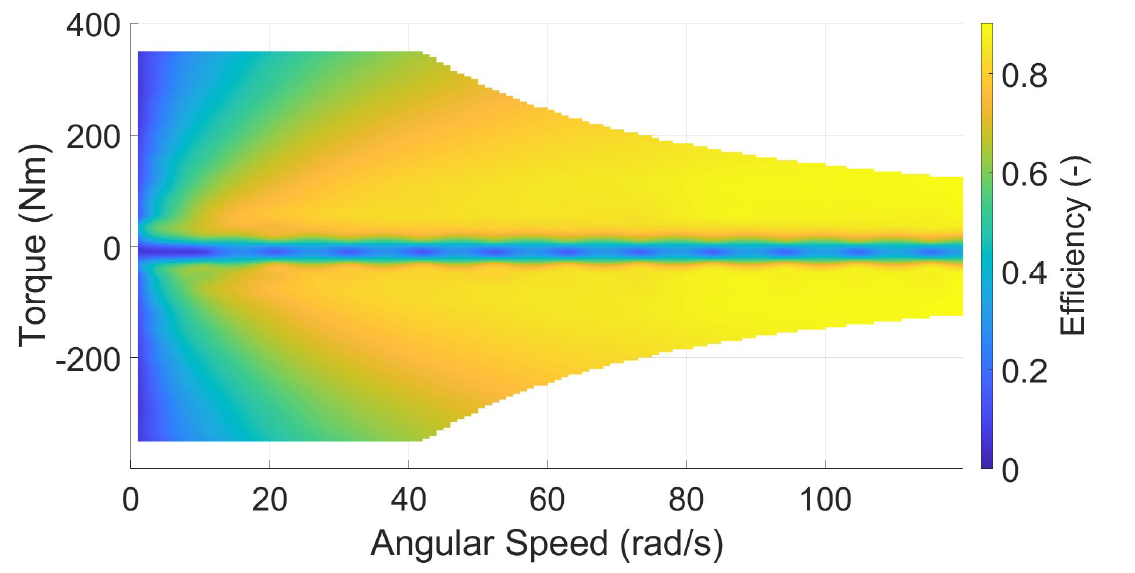

Weitere Daten: 48 V nom; 17,6 kg; I_max=570 Arms

P_M_nom_IW_max=11000;
M_M_nom_IW_max=250;
P_M_peak_IW_max=19500;
M_M_peak_IW_max=400;
J_M=0.05;
J_R=0.8;
epsi=(4*J_R+J_M)/r_A^2/m;

Bestimmen Sie die Eck-Drehzahlen rechnerisch und zeichnen Sie Dauermomente und Dauerleistungen über der Drezahl (idealisiert)

n_Eck_nom_IW_rpm=P_M_nom_IW_max/M_M_nom_IW_max*30/pi

n_Eck_nom_IW_rpm = 420.1690

n_Eck_peak_IW_rpm=P_M_peak_IW_max/M_M_peak_IW_max*30/pi

n_Eck_peak_IW_rpm = 465.5282

Welchen Geschwindigkeiten entsprechen die Eckdrehzahlen?

v_Eck_nom_IW_kph=pi/30*n_Eck_nom_IW_rpm*r_A*3.6

v_Eck_nom_IW_kph = 47.5200

v_Eck_peak_IW_kph=pi/30*n_Eck_peak_IW_rpm*r_A*3.6

v_Eck_peak_IW_kph = 52.6500

grafische Darstellung der Momente

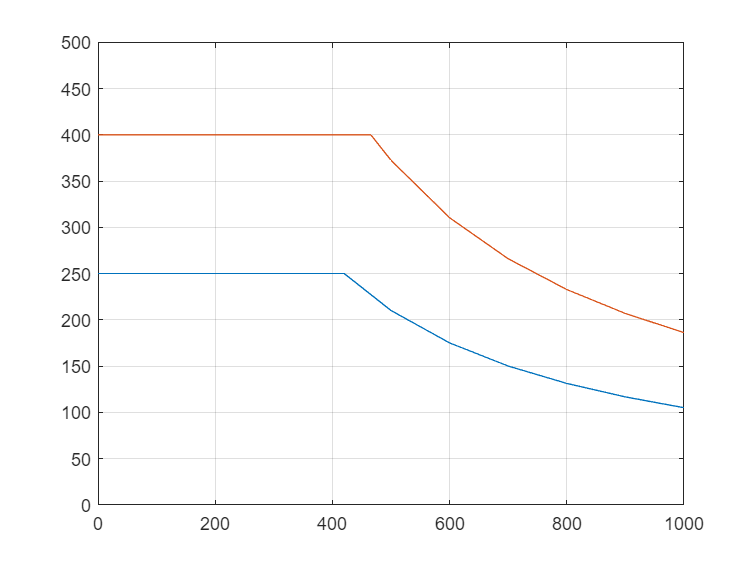

n_plot_nom_IW_rpm=[(0:100:n_Eck_nom_IW_rpm),[n_Eck_nom_IW_rpm (500:100:1000)]];
n_plot_peak_IW_rpm=[(0:100:n_Eck_peak_IW_rpm),[n_Eck_peak_IW_rpm (500:100:1000)]];
om_plot_nom_IW_1ps=pi/30*n_plot_nom_IW_rpm;
om_plot_peak_IW_1ps=pi/30*n_plot_peak_IW_rpm;
M_M_nom_IW_100=min(M_M_nom_IW_max,P_M_nom_IW_max./om_plot_nom_IW_1ps);
P_M_nom_IW_100=M_M_nom_IW_100.*om_plot_nom_IW_1ps;
M_M_peak_IW_100=min(M_M_peak_IW_max,P_M_peak_IW_max./om_plot_peak_IW_1ps);
P_M_peak_IW_100=M_M_peak_IW_100.*om_plot_peak_IW_1ps;
figure
plot(n_plot_nom_IW_rpm,M_M_nom_IW_100,n_plot_peak_IW_rpm,M_M_peak_IW_100)
grid on
xlim([0,1000])
ylim([0,500])

Welche Steigung kann mit langsamer Geschwindigkeit (vernachlässigung des Luftwiderstands) dauerhaft befahren werden?

F_A100_IW_nom=2*M_M_nom_IW_max/r_A

F_A100_IW_nom = 1.6667e+03

alpha_IW_rad=asin((F_A100_IW_nom-m*g*f_R)/(m*g));
alpha_IW_deg=alpha_IW_rad*180/pi;
q=100*tan(alpha_IW_rad)

q = 21.2452

Welche Beschleunigung ist beim Anfahren kurzzeitig möglich? 

F_A100_IW_peak=2*M_M_peak_IW_max/r_A

F_A100_IW_peak = 2.6667e+03

a1_IW=(F_A100_IW_peak-m*g*f_R)/(m+(4*J_R+J_M)/r_A^2)

a1_IW = 3.1738

Optional: Dauer des Beschleunigungsvorganges von 0 auf 50 km/h

v_50_mps=50/3.6;
a2_IW=(F_A100_IW_peak-m*g*f_R-c_w*A*rho/2*v_50_mps^2)/(m+(4*J_R+J_M)*r_A^2)

a2_IW = 3.2275

a_m_IW=(a1_IW+a2_IW)/2

a_m_IW = 3.2006

T_IW=v_50_mps/a_m_IW

T_IW = 4.3394

Drehzahl, mögliches Drehmoment bei 90 km/h

v_lim_kph=90;
v_lim_mps=v_lim_kph/3.6;
nA_lim_rpm=v_lim_mps/r_A*30/pi

nA_lim_rpm = 795.7747

M_M_lim_IW=2*min(M_M_nom_IW_max,P_M_nom_IW_max/(nA_lim_rpm*pi/30))

M_M_lim_IW = 264.0000

Welche Energie muss die Batterie zur Verfügung stellen, wenn bei 50 km/h eine Stunde gefahren wird?

v50_mps = 50/3.6;
n_v50_IW_rpm = 30/pi*v50_mps/r_A

n_v50_IW_rpm = 442.0971

F_A50 = m*g*f_R + c_w*A*rho/2*v50_mps^2;
M_v50_IW = 0.5*F_A50*r_A

M_v50_IW = 22.2416

P_v50 = F_A50*v50_mps

P_v50 = 2.0594e+03

eta_v50 = 0.75;
P_v50_el = P_v50/eta_v50

P_v50_el = 2.7459e+03

Welche Energie muss die Batterie zur Verfügung stellen, wenn bei 90 km/h eine Stunde gefahren wird?

v90_mps = 90/3.6;
n_v90_IW_rpm = 30/pi*v90_mps/r_A

n_v90_IW_rpm = 795.7747

F_A90 = m*g*f_R + c_w*A*rho/2*v90_mps^2;
M_v90_IW = 0.5*F_A90*r_A

M_v90_IW = 46.3527

P_v90 = F_A90*v90_mps

P_v90 = 7.7255e+03

eta_v90 = 0.83;
P_v90_el = P_v90/eta_v90

P_v90_el = 9.3078e+03

## Batterie (Winston WB-LYP100AHA)

Als Akkumulator soll eine LFP Batterie mit Nennspannung von 48V konzeptioniert werden.

Als Zellen stehen zur Verfügung:

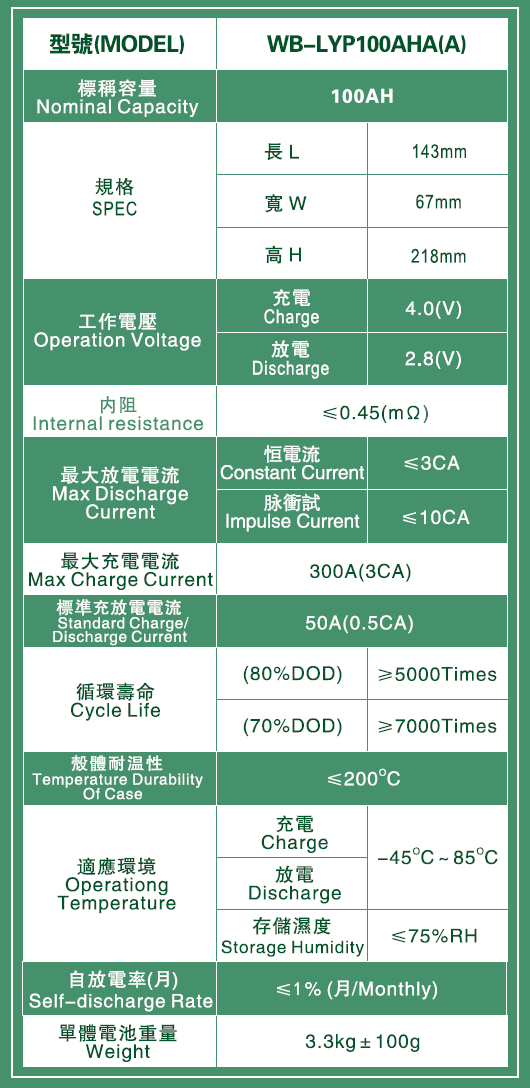

Welchen Aufbau der Batterie wählen Sie?

16s2p

Bestimmen Sie den Entladestrom bei einer Fahrt mit 90 km/h.

Aus Maschengleíchung

 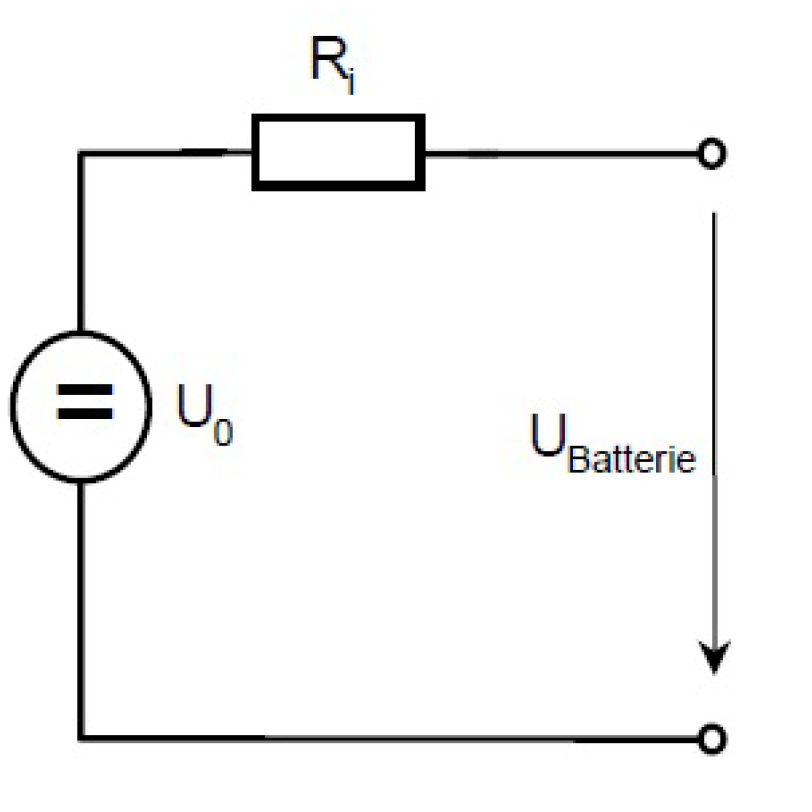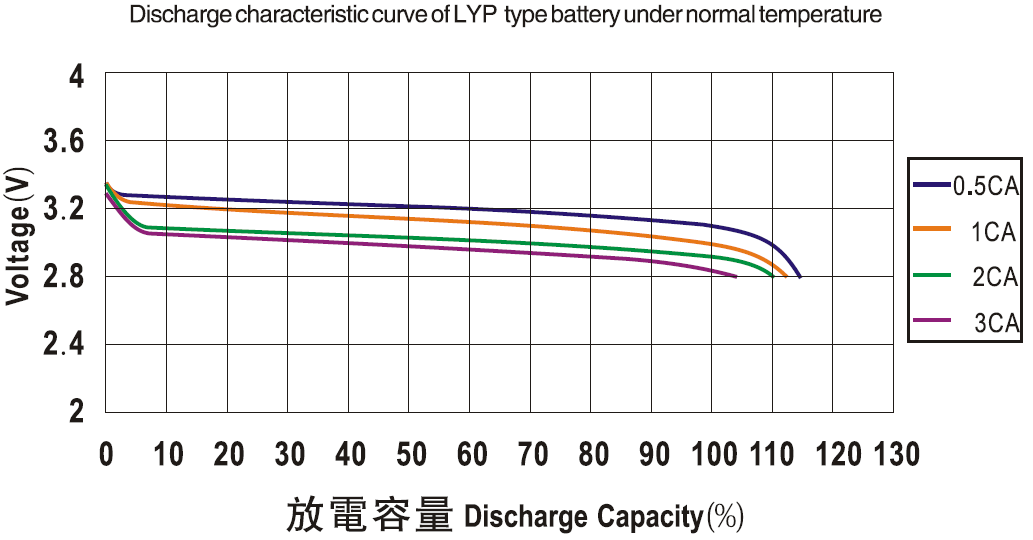

%R_i = 0.45E-03;
R_i_Cell = 1E-03; % Abgelesen aus Diagramm
U_min_Cell = 3;
U_0_Cell=3.2;
U_min_Bat = 48;
num_s = U_min_Bat/U_min_Cell;
R_i_s = num_s*R_i_Cell;
U_0_Bat = num_s*U_0_Cell 

U_0_Bat = 51.2000

I_Bat=roots([R_i_s/2 -U_0_Bat P_v90_el]);
I_Bat_v90=I_Bat(2)

I_Bat_v90 = 187.2722

Welcher C-Rate (bezogen auf die Zelle) entspricht dies?

I_Cell_v90=I_Bat_v90/2

I_Cell_v90 = 93.6361

Welcher Entladewirkungsgrad liegt dann vor?

eta_Bat_v90 = 1-(R_i_s*I_Bat_v90^2)/(U_0_Bat*I_Bat_v90)

eta_Bat_v90 = 0.9415

Welcher Entladestrom und welcher Wirkungsgrad ergibt sich bei 50 km/h

I_Bat=roots([R_i_s/2 -U_0_Bat P_v50_el]);
I_Bat_v50=I_Bat(2)

I_Bat_v50 = 54.0875

I_Cell_v50=I_Bat_v50/2

I_Cell_v50 = 27.0437

eta_Bat_v50 = 1-(R_i_s/2*I_Bat_v50^2)/(U_0_Bat*I_Bat_v50)

eta_Bat_v50 = 0.9915

Welche Leistung kann **maximal** (dauerhaft) aus der Batterie eintnommen werden?

U_Cell_3C = 2.9;
I_max = 300;
P_Bat_max=2*I_max*U_Cell_3C*num_s

P_Bat_max = 27840

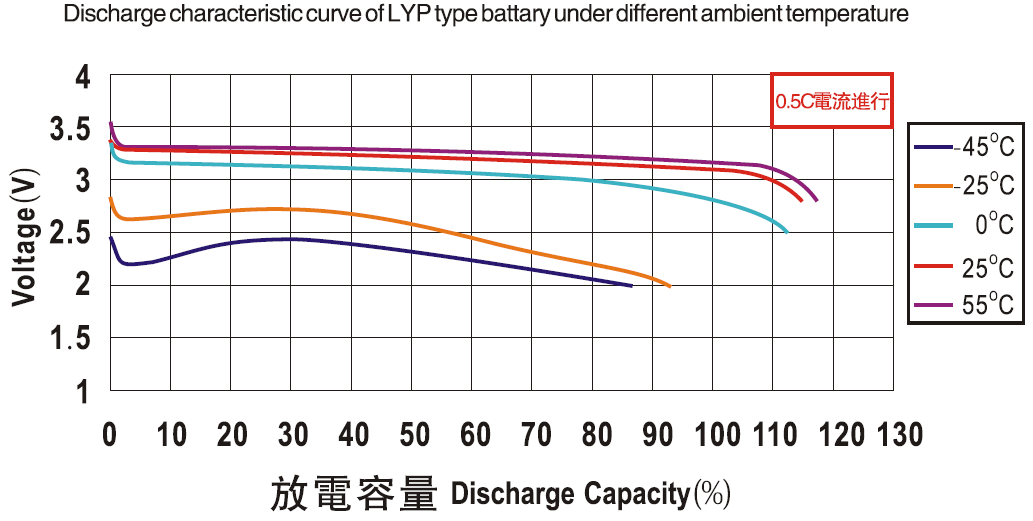

Welche Leistung kann bei 0°C noch aus der Batterie entnommen werden, wenn der Innenwiderstand der Zelle dabei auf Ri=0.064 Ohm ansteigt ?

R_i_cold = 0.064;
P_Bat_cold = (U_0_Bat - R_i_cold/2*2*I_max) * 2*I_max

P_Bat_cold = 19200

Die Ansteuerung der Radnabenmotoren soll genauer betrachtet werden. Für einen Wicklungsstrang der Motoren gilt:

% Daten Elektromotor (Recherche Internet, Daten R,L von QS Motor, Polparzahl von elaphe)
R = 0.1;
L = 300E-06;
z_p = 16;

Das Fahrzeug wird mit 47 km/h im Grunddrehzahlbereich angetrieben. Gehen Sie davon aus, dass im Grunddrehzahlbereich die Magnetfelder von Stator und Rotor senkrecht aufeinander stehen. Jeder Motor dreht mit n_M=416 min-1 und liefert ein Moment von M_M=21 Nm. Bestimmen Sie die erforderliche Strangspannung U_{St} und die elektrische Frequenz f_{el} der angelegten Wechselspannung. 

M = 21; 
n_s = 416; 
om = pi/30*n_s;
eta = 0.8; 

om_el=om*z_p;
c_u=sqrt(eta*R*M/(3*(1-eta)*om))

c_u = 0.2535

I=M/(3*c_u)

I = 27.6109

U=sqrt((om_el*L*I)^2+(c_u*om + R*I)^2)

U = 14.9641

csp = (c_u*om + R*I)/U

csp = 0.9226

Kontrolle der Werte

disp(['el. Leistung=',num2str(3*U*I*csp)])

el. Leistung=1143.5397


disp(['mech. Leistung=',num2str(M*om)])

mech. Leistung=914.8318


disp(['Wirkungsgrad=',num2str(om*M/(3*U*I*csp))])

Wirkungsgrad=0.8


disp(['Moment aus Strom=',num2str(3*c_u*I)])

Moment aus Strom=21


disp(['induzierte Spannung=',num2str(c_u*om)])

induzierte Spannung=11.0443


disp(['Luftspaltleistung=',num2str(3*c_u*om*I)])

Luftspaltleistung=914.8318
